A.GPSDate.Format = "dd/MM/uuuu HH:mm:ss";
A.gpsTime.Format = "dd/MM/uuuu HH:mm:ss";

A.Date = A.GPSDate + timeofday(A.gpsTime);

A.GPSDate = [];
A.gpsTime = [];

A = movevars(A, "Date", "After", "JulianDate");

writetable(A, "RenateTrans.csv", "Delimiter", "\t");

A.Type = string(A.Type);

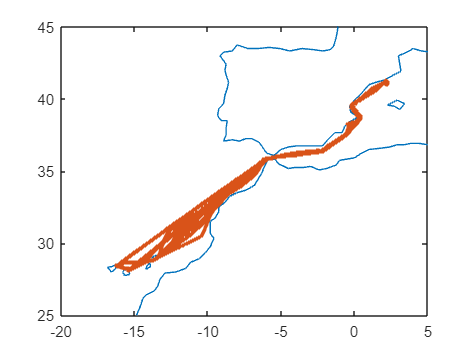

load coastlines.mat
plot(coastlon, coastlat)
hold on
plot(A.longitude, A.latitude, ".")
hold off
xlim([-20 5])
ylim([25 45])

% Seleccionar datos en el mediterráneo
Mrows = A(A.longitude > -13, :);

load coastlines.mat
plot(coastlon, coastlat)
hold on
plot(Mrows.longitude, Mrows.latitude, ".")
hold off
xlim([-20 5])
ylim([25 45])

% Seleccionar datos en las islas 
TLrows = A(A.longitude > -16.20 & A.longitude < -12, :);

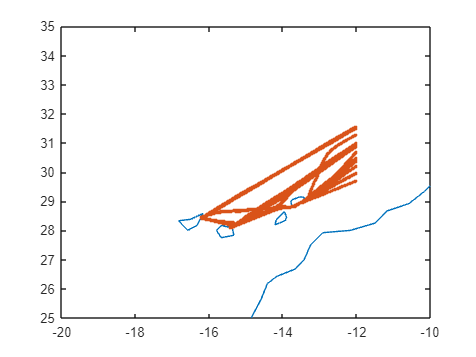

load coastlines.mat
plot(coastlon, coastlat)
hold on
plot(TLrows.longitude, TLrows.latitude, ".")
hold off
xlim([-20 -10])
ylim([25 35])

% Seleccionar solo las filas que sean medidas de equilibrador
TLrowsEqu = TLrows(TLrows.Type == "EQU", :);
TLrowsEqu.DiffTSGint = TLrowsEqu.TEMP - TLrowsEqu.IntakeTemp;

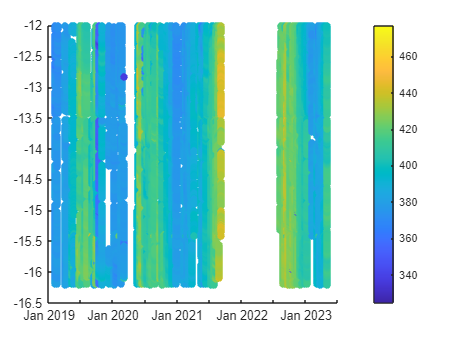

scatter(TLrowsEqu.Date, TLrowsEqu.longitude, [], TLrowsEqu.fCO2sw, "filled")
colorbar;

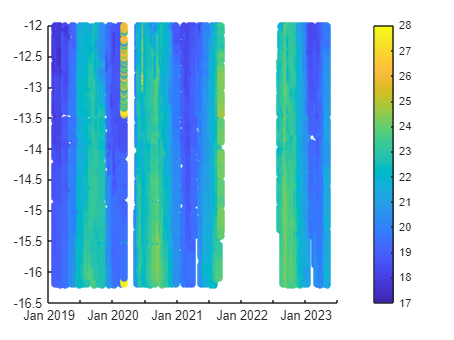

scatter(TLrowsEqu.Date, TLrowsEqu.longitude, [], TLrowsEqu.IntakeTemp, "filled")
colorbar;

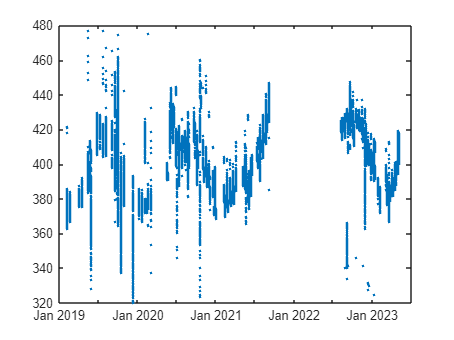

plot(TLrowsEqu.Date, TLrowsEqu.fCO2sw, ".")

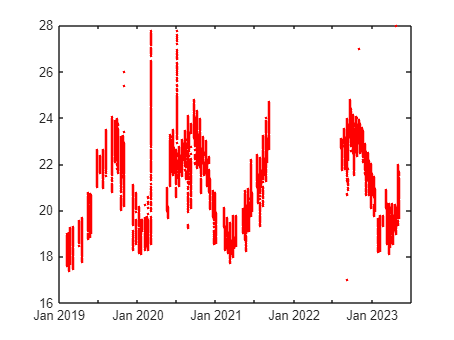

plot(TLrowsEqu.Date, TLrowsEqu.IntakeTemp, ".r")

% Hallar datos malos de fCO2
badCO2 = find(TLrowsEqu.fCO2sw > 480| TLrowsEqu.fCO2sw < 320);
badTemp = find(TLrowsEqu.IntakeTemp > 30 | TLrowsEqu.IntakeTemp < 14);

% Eliminar malas medidas de fCO2 y Temperatura
TLrowsEqu.fCO2sw(badCO2) = NaN;
TLrowsEqu.IntakeTemp(badTemp) = NaN;

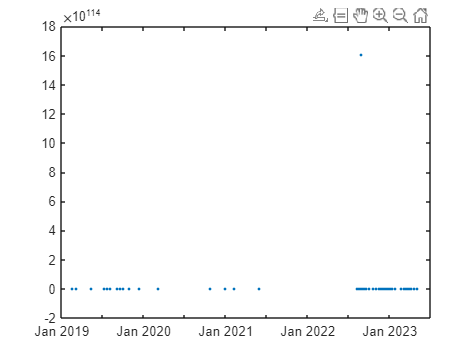

plot(TLrowsEqu.Date(badCO2), TLrowsEqu.fCO2sw(badCO2), ".")

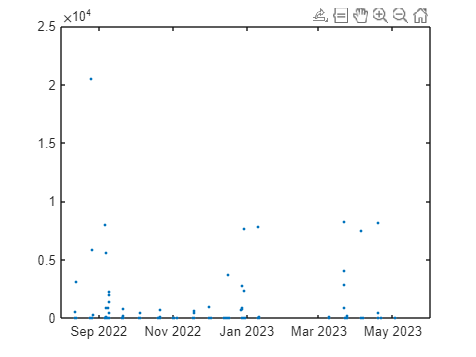

plot(TLrowsEqu.Date(badTemp), TLrowsEqu.IntakeTemp(badTemp), ".")

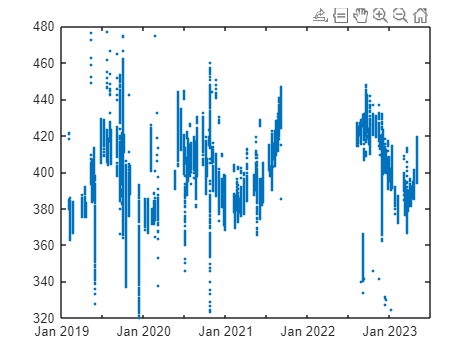

plot(TLrowsEqu.Date, TLrowsEqu.fCO2sw, ".")

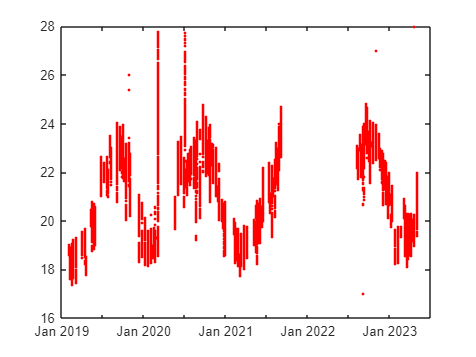

plot(TLrowsEqu.Date, TLrowsEqu.IntakeTemp, "r.")

% Encontrar medidas con flujos de agua malos
badWater = find(TLrowsEqu.H2OFlow > 5 | TLrowsEqu.H2OFlow < 1.5);
badLicor = find(TLrowsEqu.licorFlow < 60);
badDiff = find(TLrowsEqu.DiffTSGint > 1.5 | TLrowsEqu.DiffTSGint < 0);

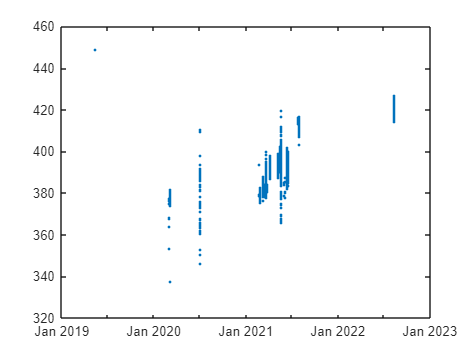

plot(TLrowsEqu.Date(badWater), TLrowsEqu.fCO2sw(badWater), ".")

% plot(TLrowsEqu.Date(badLicor), TLrowsEqu.fCO2sw(badLicor), ".")
% plot(TLrowsEqu.Date(badTemp), TLrowsEqu.fCO2sw(badTemp), ".")

% TLrowsEqu.fCO2sw(badWater) = NaN;
% TLrowsEqu.fCO2sw(badLicor) = NaN;
% TLrowsEqu.fCO2sw(badTemp) = NaN;

TLrowsEqu.IntakeTemp(22327:22407) = NaN;
TLrowsEqu.IntakeTemp(22731:23193) = NaN;
TLrowsEqu.IntakeTemp(27697:28023) = NaN;

badWater1 = badWater(2:522);
badWater2 = badWater(523:834);
badWater3 = badWater(2746:4083);


TLrowsEqu.fCO2sw(badWater1) = NaN;
TLrowsEqu.fCO2sw(badWater2) = NaN;
TLrowsEqu.fCO2sw(badWater3) = NaN;
TLrowsEqu.fCO2sw(17186:17345) = NaN;
TLrowsEqu.fCO2sw(61637:62354) = NaN;
TLrowsEqu.fCO2sw(10387:10697) = NaN;
TLrowsEqu.fCO2sw(70717:70797) = NaN;

TLrowsEqu.fCO2sw(12570:12786) = NaN;

TLrowsEqu.fCO2sw(16973:17032) = NaN;
TLrowsEqu.fCO2sw(6086:6654) = NaN;
TLrowsEqu.fCO2sw(11832:12569) = NaN;
TLrowsEqu.fCO2sw(15103:16097) = NaN;
%TLrowsEqu.fCO2sw(6086:6654) = NaN;

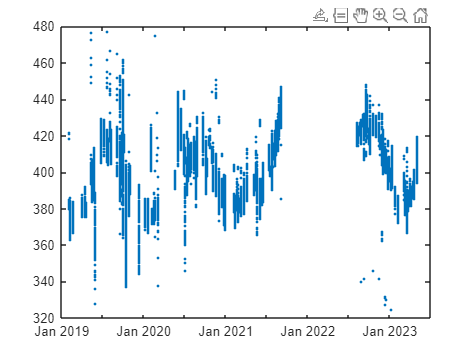

plot(TLrowsEqu.Date, TLrowsEqu.fCO2sw, ".")

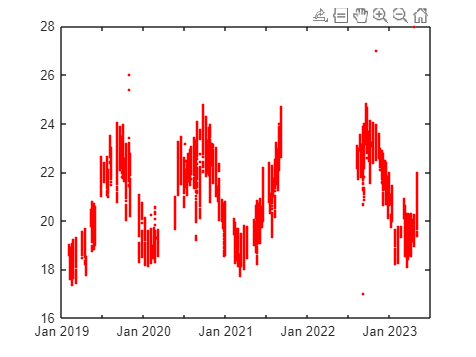

plot(TLrowsEqu.Date, TLrowsEqu.IntakeTemp, "r.")

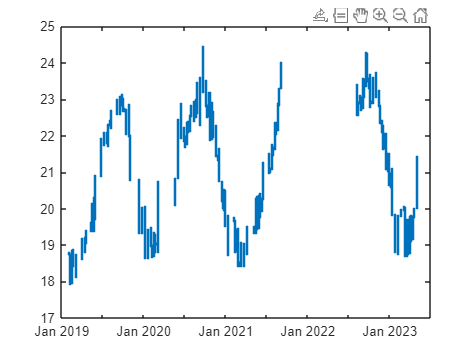

plot(TLrowsEqu1.Date, TLrowsEqu1.IntakeTemp, ".")

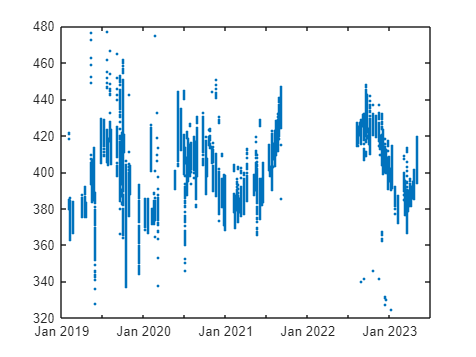

plot(TLrowsEqu.Date, TLrowsEqu.fCO2sw, ".")

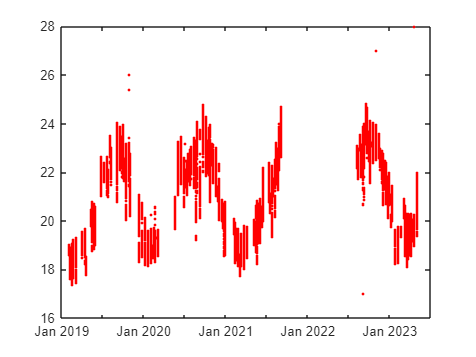

plot(TLrowsEqu.Date, TLrowsEqu.IntakeTemp, "r.")

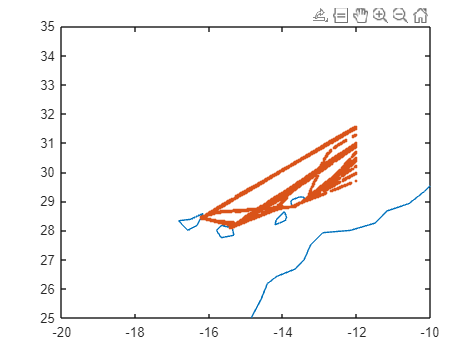

load coastlines.mat
plot(coastlon, coastlat)
hold on
plot(CleanfCO2.longitude, CleanfCO2.latitude, ".")
hold off
xlim([-20 -10])
ylim([25 35])

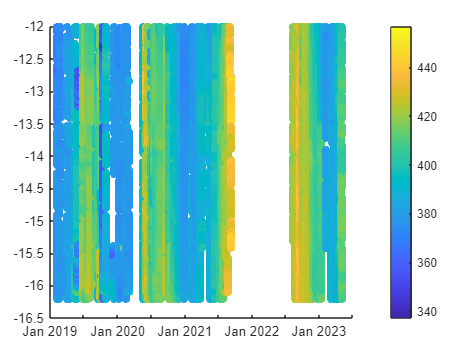

scatter(CleanfCO2.Date, CleanfCO2.longitude, [], CleanfCO2.fCO2sw, "filled")
colorbar;

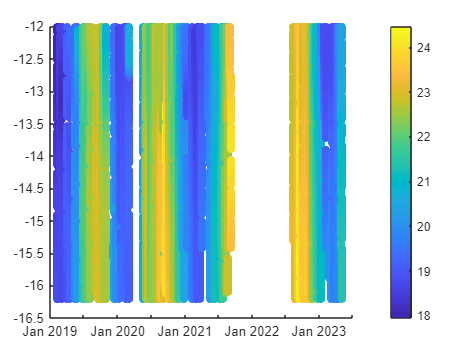

ylabel("Longitude")
title("")
scatter(CleanIntake.Date, CleanIntake.longitude, [], CleanIntake.IntakeTemp, "filled")
colorbar;

% Trayecto entre Tenerife y Lanzarote
TLcleanCO2 = CleanfCO2(CleanfCO2.longitude > -16.15 & CleanfCO2.longitude < -13.75 & CleanfCO2.latitude > 28.4 & CleanfCO2.latitude < 28.85, :);
TLcleanTemp = CleanIntake(CleanIntake.longitude > -16.15 & CleanIntake.longitude < -13.75 & CleanIntake.latitude > 28.4 & CleanIntake.latitude < 28.85, :);

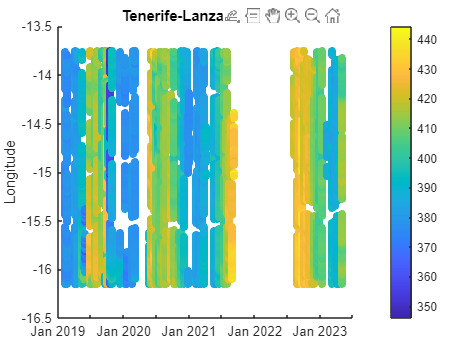

scatter(TLcleanCO2.Date, TLcleanCO2.longitude, [], TLcleanCO2.fCO2sw, "filled")
colorbar;
ylabel("Longitude")
title("Tenerife-Lanzarote fCO2")

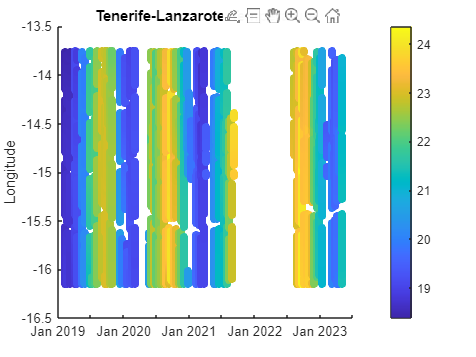

scatter(TLcleanTemp.Date, TLcleanTemp.longitude, [], TLcleanTemp.IntakeTemp, "filled")
ylabel("Longitude")
title("Tenerife-Lanzarote Temperature")
colorbar;

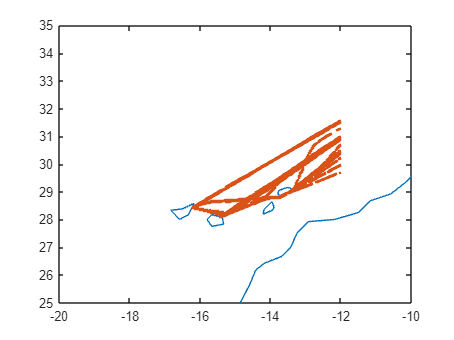

plot(coastlon, coastlat)
hold on
plot(TLrowsEqu.longitude, TLrowsEqu.latitude, ".")
hold off
xlim([-20 -10])
ylim([25 35])

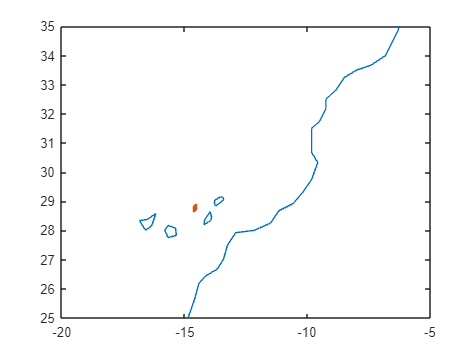

% Punto elegido : -14.55 (-14.60:-14.50) 28.73:28.83
locTLco2 = CleanfCO2(CleanfCO2.longitude > -14.60 & CleanfCO2.longitude < -14.50 & CleanfCO2.latitude > 28.65 & CleanfCO2.latitude < 28.9, :);
locLco2 = CleanfCO2(CleanfCO2.longitude > -13.35 & CleanfCO2.longitude < -13.25 & CleanfCO2.latitude < 29.4, :); 
locTLtemp = CleanIntake(CleanIntake.longitude > -14.60 & CleanIntake.longitude < -14.50 & CleanIntake.latitude > 28.65 & CleanIntake.latitude < 28.9, :);
locLtemp = CleanIntake(CleanIntake.longitude > -13.35 & CleanIntake.longitude < -13.25 & CleanIntake.latitude < 29.4, :); 
%locTL = TLrowsEqu(TLrowsEqu.longitude > -14.60 & TLrowsEqu.longitude < -14.50, :);

plot(coastlon, coastlat)
hold on
plot(locTLco2.longitude, locTLco2.latitude, ".")
hold off
xlim([-20 -5])
ylim([25 35])

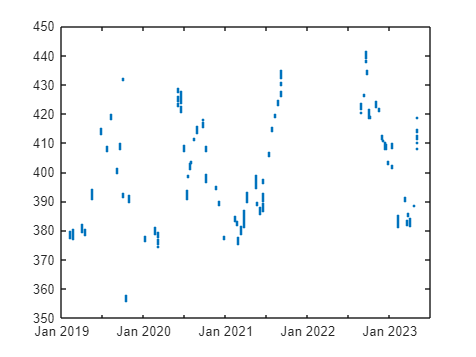


plot(locTLco2.Date, locTLco2.fCO2sw, ".")

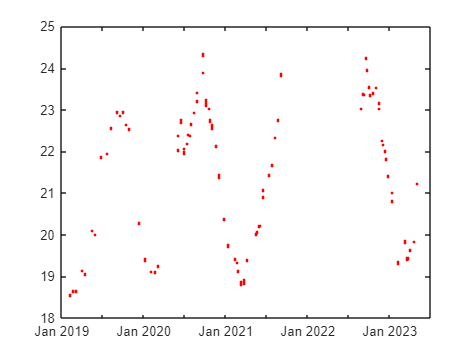

plot(locTLtemp.Date, locTLtemp.IntakeTemp, "r.")

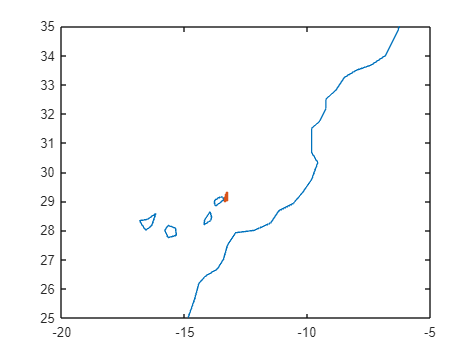


plot(coastlon, coastlat)
hold on
plot(locLtemp.longitude, locLtemp.latitude, ".")
hold off
xlim([-20 -5])
ylim([25 35])

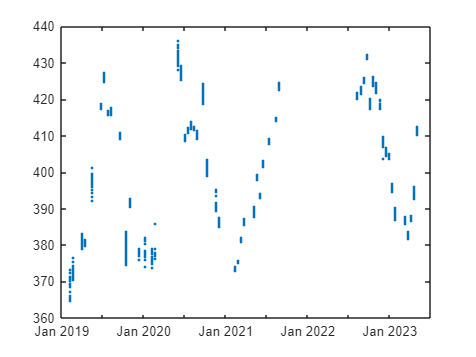

plot(locLco2.Date, locLco2.fCO2sw, ".")

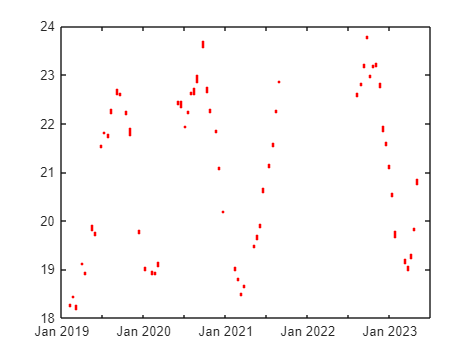

plot(locLtemp.Date, locLtemp.IntakeTemp, "r.")

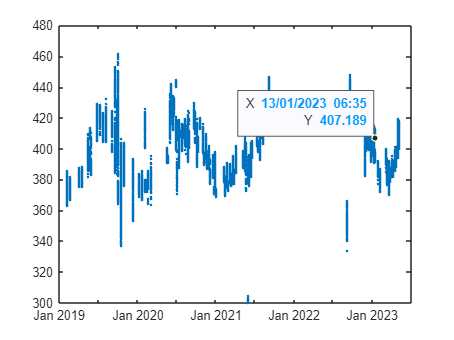

TLrowsEqu1.fCO2sw(3728:3890) = NaN; %'30/05/2019 18:52'-'30/05/2019 23:58'
TLrowsEqu1.fCO2sw(7299:7756) = NaN; %'02/10/2019 09:46'-'03/10/2019 12:49'
TLrowsEqu1.fCO2sw(10172:10251) = NaN; %'12/12/2019 07:44'-'12/12/2019 09:20'
TLrowsEqu1.fCO2sw(10385:10544) = NaN; %12/12/2019 23:02-13/12/2019 03:32
TLrowsEqu1.fCO2sw(11968:12131) = NaN;%'05/02/2020 13:47'-'06/02/2020 03:54'
TLrowsEqu1.fCO2sw(21284:21584) = NaN; %22/10/2020 20:07-'22/10/2020 21:39'
TLrowsEqu1.fCO2sw(29590:29919) = NaN; %01/06/2021-02/06/2021 05:09
TLrowsEqu1.fCO2sw(38882:38959) = NaN; %'29/11/2022 21:33'-'29/11/2022 23:59'

TLrowsEqu1.fCO2sw(34201:34592) = NaN; % 06/09/2022 - 07/09/2022 06:38

TLrowsEqu1.fCO2sw(34112) = NaN;%26/08/2022 01:58
%badCO2sec = find(TLrowsEqu1.fCO2sw > 470| TLrowsEqu.fCO2sw < 340);
%TLrowsEqu1.fCO2sw(badCO2sec) = NaN;
%plot(TLrowsEqu11.Date, TLrowsEqu11.fCO2sw, ".")

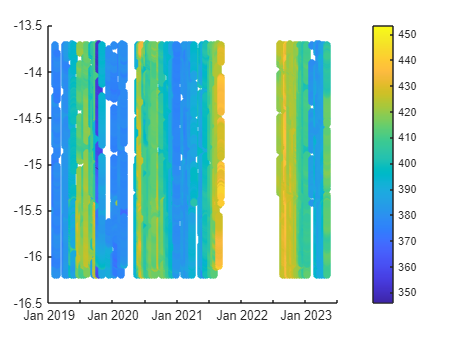

scatter(TLrowsEqu1.Date, TLrowsEqu1.longitude, [], TLrowsEqu1.fCO2sw, "filled")

colorbar;

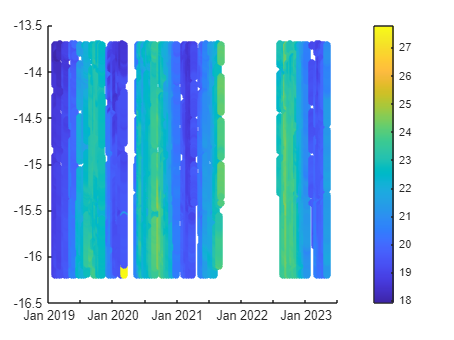

scatter(TLrowsEqu1.Date, TLrowsEqu1.longitude, [], TLrowsEqu1.IntakeTemp, "filled")
colorbar;

badTemp = find(TLrowsEqu1.IntakeTemp > 30 | TLrowsEqu1.IntakeTemp < 10);

TLrowsEqu1.IntakeTemp(badTemp) = NaN;

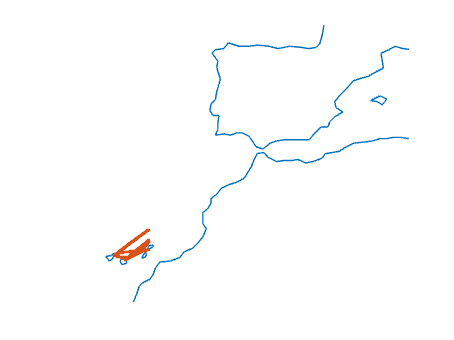

plot(coastlon, coastlat)
hold on
plot(TLrows.longitude, TLrows.latitude, ".")
hold off
xlim([-20 5])
ylim([25 45])

islands = readgeotable("islas.geojson");

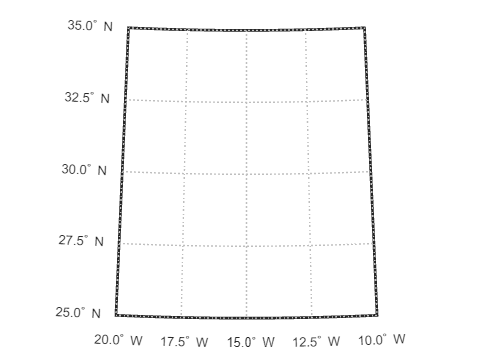

worldmap("Canary Islands");

geoshow(islands);
